nwb = nwbRead('ShuoYen/sub-8_ses-20200204T180138_ophys.nwb');

ophys = get(nwb.processing, 'ophys');
fluorescence = get(ophys.nwbdatainterface, 'Fluorescence');

roi_response = get(fluorescence.roiresponseseries, 'Plane_0');
dff = roi_response.data.load();              
timestamps = roi_response.timestamps.load(); 

odor = get(nwb.stimulus_presentation, 'odor');
stim_timestamps = odor.timestamps.load();  
stim_labels = odor.data.load();            

% 確保 stim_labels 與 stim_timestamps 為 column vector
stim_labels = stim_labels(:);
stim_timestamps = stim_timestamps(:);

% 找出氣味變化點（onset）
odor_onset_idx = find([true; diff(stim_labels) ~= 0]);

% 抓出 onset 對應時間與氣味 label
odor_onset_times = stim_timestamps(odor_onset_idx);
odor_onset_labels = stim_labels(odor_onset_idx);

% 篩掉無效 label（背景或 NaN）
valid_mask = ~isnan(odor_onset_labels) & odor_onset_labels >= 0;
odor_onset_times = odor_onset_times(valid_mask);
odor_onset_labels = odor_onset_labels(valid_mask);

% 👉 可選：過濾太短間隔（如果你發現某些氣味持續時間太短）
% min_interval = 3; % 單位秒
% keep = [true; diff(odor_onset_times) > min_interval];
% odor_onset_times = odor_onset_times(keep);
% odor_onset_labels = odor_onset_labels(keep);

resp_window = [0, 2];         % 分析視窗（刺激後）
baseline_window = [-1, 0];    % 基線視窗（刺激前）

fps = 1 / median(diff(timestamps));
resp_frames = round(resp_window * fps);
base_frames = round(baseline_window * fps);

n_cells = size(dff, 1);
n_odors = 10;
trial_responses = zeros(n_cells, length(odor_onset_times));

for i = 1:length(odor_onset_times)
    t0 = odor_onset_times(i);
    [~, onset_idx] = min(abs(timestamps - t0));
    
    base_idx = onset_idx + base_frames(1):onset_idx + base_frames(2);
    resp_idx = onset_idx + resp_frames(1):onset_idx + resp_frames(2);

    if min(base_idx) < 1 || max(resp_idx) > size(dff, 2)
        trial_responses(:, i) = NaN;
        continue;
    end

    F0 = mean(dff(:, base_idx), 2);
    F_resp = mean(dff(:, resp_idx), 2);
    dff_trial = (F_resp - F0) ./ F0;

    trial_responses(:, i) = dff_trial;
end

% 平均每個氣味反應
mean_responses = zeros(n_cells, n_odors);
for odor = 1:n_odors
    idx = find(odor_onset_labels == odor);
    mean_responses(:, odor) = mean(trial_responses(:, idx), 2, 'omitnan');
end

% heatmap
figure;
imagesc(mean_responses);

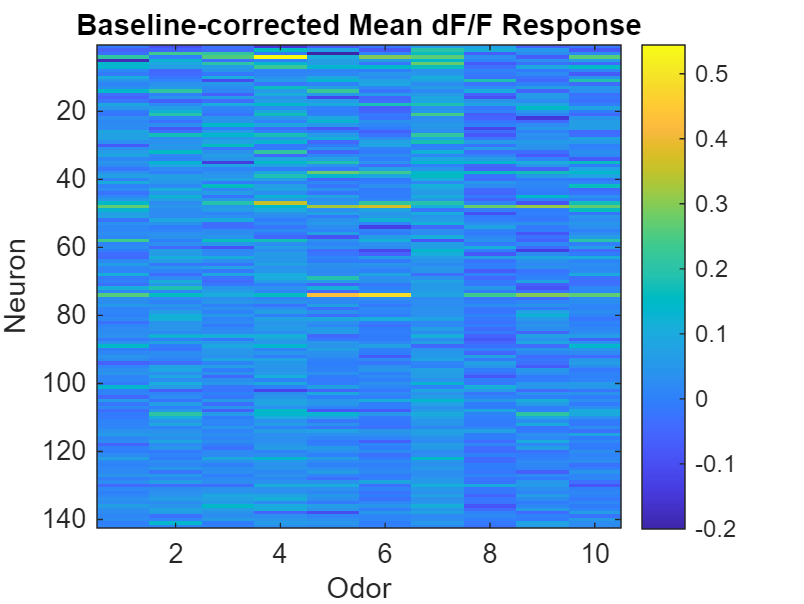

xlabel('Odor'); ylabel('Neuron');
title('Baseline-corrected Mean dF/F Response');
colorbar;

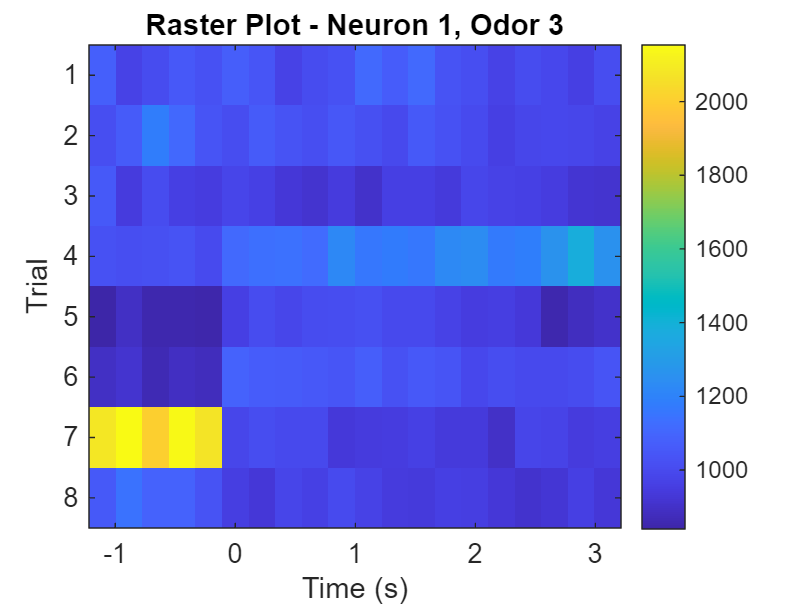

neuron_id = 1;    
target_odor = 3;  
window = [-1, 3]; 

fps = 1 / median(diff(timestamps));
win_frames = round(window(1) * fps):round(window(2) * fps);
t_axis = win_frames / fps;

trial_idx = find(odor_onset_labels == target_odor);
n_trials = length(trial_idx);
raster_data = zeros(n_trials, length(win_frames));

for i = 1:n_trials
    t0 = odor_onset_times(trial_idx(i));
    [~, onset_idx] = min(abs(timestamps - t0));
    idx = onset_idx + win_frames;

    if min(idx) < 1 || max(idx) > length(timestamps)
        raster_data(i, :) = NaN;
        continue;
    end

    raster_data(i, :) = dff(neuron_id, idx);
end

% raster plot
figure;
imagesc(t_axis, 1:n_trials, raster_data);
xlabel('Time (s)'); ylabel('Trial');
title(sprintf('Raster Plot - Neuron %d, Odor %d', neuron_id, target_odor));
colorbar;

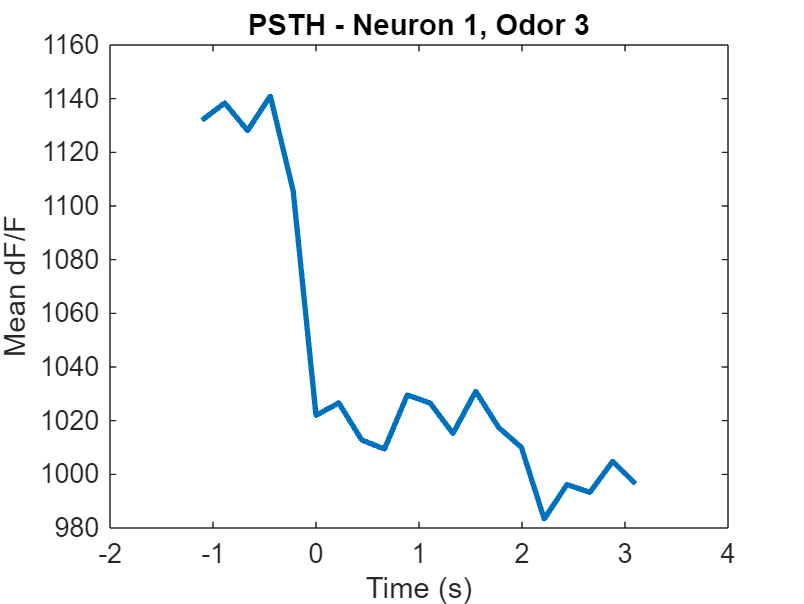


% PSTH
mean_trace = nanmean(raster_data, 1);
figure;
plot(t_axis, mean_trace, 'LineWidth', 2);
xlabel('Time (s)'); ylabel('Mean dF/F');
title(sprintf('PSTH - Neuron %d, Odor %d', neuron_id, target_odor));